In questo live script andiamo a vedere come tarare gli attributi di un pid.

In particolare vedremo l'implementazione di tre controllori:

- P: azione proporzionale, solo guadagno

- PI: azione integrativa e proporzionale

- PID: azione proporzionale, integrativa, derivativa

Cominciamo dal determinare P: 

il metodo che utilizziamo è quello di Ziegler Nichols, in particolare quello ad anello chiuso

Dopo diverse prove e m

isurazioni viene fuori un k critico di circa 2.666, seguendo la tabella per decretare il $k_p$ vado a moltiplicare per 0.5 $\Rightarrow k_p = 1.333$

Quindi il nostro P sarà equivalente a quello che c'è il simulink.

Per costruire il PI oltre a conoscere k_p dobbiamo conoscere anche il periodo T che vediamo tra le oscillazioni costanti 

open("simulink_progetto_esercizio1.slx")

Viene fuori che T = 3.839

Utilizziamo la tabella per calcolare i parametri di PI e PID

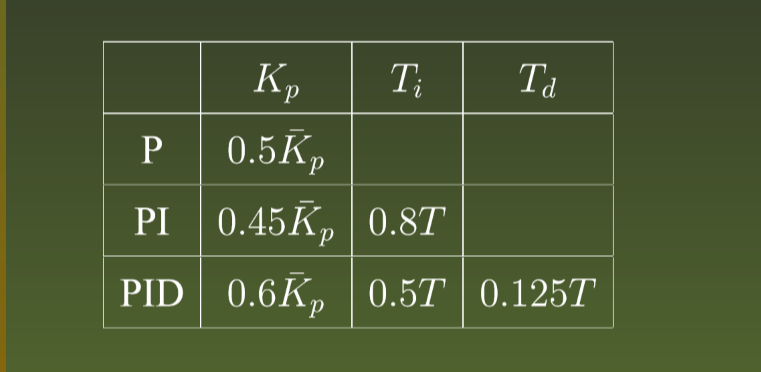

Quindi per il PI avremo :

k_p2 = 0.45 * 2.666

k_p2 = 1.1997

T_i = 0.8 * 3.839

T_i = 3.0712

Per il PID finale avremo : 

k_p4 = 0.6 * 2.666

k_p4 = 1.5996

T_i2 = 0.5 * 3.839

T_i2 = 1.9195

integ = 1/T_i2

integ = 0.5210

T_d2 = 0.125 * 3.839

T_d2 = 0.4799

%stepinfo(out.Y, "SettlingTimeThreshold", 0.05)
stepinfo(out.Y1, "SettlingTimeThreshold",0.05)

Unable to resolve the name 'out.Y1'.